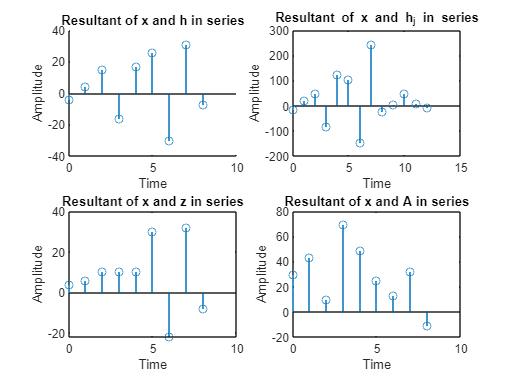

clc
clear all
% Given signals
x = [2 1 -2 4 -1];
h = [-2 3 4 -3 7];
j = [4 -1 2 3 1];
k = [6 5 4 3 2];
% Convolution of x and h
y = conv(x,h);
% Convolution of h and j
h_j = conv(h,j);
% Convolution of x and h_j
x_hj = conv(x,h_j);
% Convolution of x and z (z is the result of parallel combination of h and j)
z = conv(h,[1]) + conv(j,[1]);
result = conv(x,z);
% Parallel combination of k and h_j
A = length(h_j) + conv(k,[1]);
% Convolution of x and A
y_overall = conv(x,A);
% Plotting the results
t1 = 0:length(y)-1;
subplot(2,2,1)
hold on
stem(t1,y);
title('Resultant of x and h in series');
xlabel('Time');
ylabel('Amplitude');
t2 = 0:length(x_hj)-1;
subplot(2,2,2)
stem(t2,x_hj);
title('Resultant of x and h_j in series');
xlabel('Time');
ylabel('Amplitude');
t3 = 0:length(result)-1;
subplot(2,2,3)
stem(t3,result);
title('Resultant of x and z in series');
xlabel('Time');
ylabel('Amplitude');
t4 = 0:length(y_overall)-1;
subplot(2,2,4)
stem(t4,y_overall);
title('Resultant of x and A in series');
xlabel('Time');
ylabel('Amplitude');
hold off